# Final Project - Exner Equation Model of Erodible Beds

By: Dorien Minor and Jordan Murdock

## Introduction

The main theme of this project is to investigate the stability of an erodible bed of sand when water flows atop, which serves as a major pathway for deposition and sediment transport. Depending on the speed and perturbation velocities of the ambient flow, sand grains can become deposited to create sinusoidal-shaped waves of sand that can fall under three primary categories: dunes, antidunes and flatbeds. This topic is imortant because an understanding of the fluid-bed interface has strong implications for river and civil engineering since the roughness of a channel is determined primarily by the form of the bed and the sediment transport capacity of the flow. 

In this analysis, the forms of the bed and free surface will be idealized as two-dimensional. The flow will be treated as irrotational, and the viscosity, surface tension, and compressibility of the fluid will be neglected.

## Parameters and Equations

### Sediment Transport Process

#### Assumptions: 

- Given a fixed porosity (e = 0.6, average of typical porosity values), there is bedload transport only.

- Turbulent boundary layer exists at the bed, where the basal stress develops through a shear layer.

- Maximum stress occurs upstream of the bed maximum; this allows for turbulence to be induced within the model.

- Conservation of mass and momentum.

- Irrotational flow.

#### Derived from Fowler (2011):

u = 1; % horizontal flow velocity, [m/s]

xi = 0; % beginning of bed, [m]
xf = 100000; % final point on bed, [m]
m = 1001; % number of grid spaces
dx = xf/(m-1); % x-axis spacing, [m]
x = xi:dx:xf;

ti = 0; % initial time, [s]
tf = 86400; % ending time, [s]
dt = 10; % time step [s]
t = ti:dt:tf;
n = round(tf/dt);

C = (u*dt)/dx;

h = 10; % height of the beginning of bed, [m]
eta = linspace(h,0,m); % bed elevation relative to some fixed datum, [m]

e = 0.6; % bed porosity

**Dirichlet Boundary Conditions:**

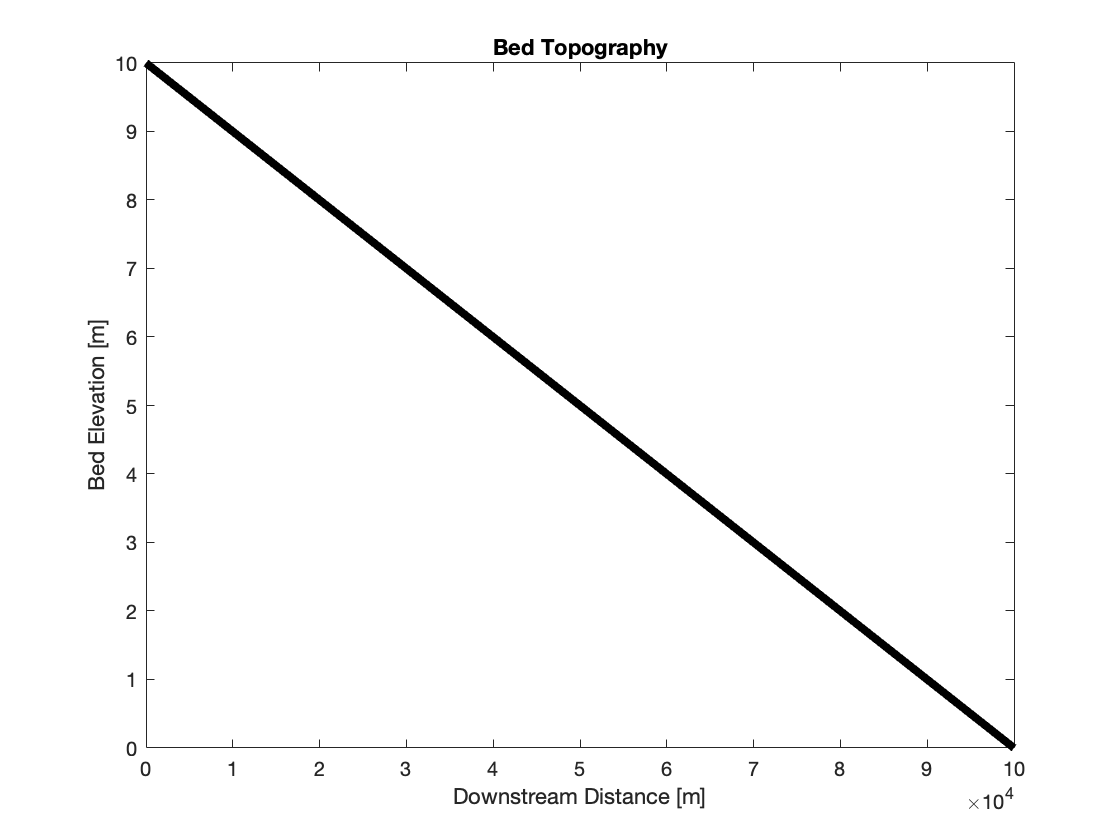

eta(1) = 10; % [m], 990 used in paper
eta(end) = 0; % [m]

figure(1)
plot(x,eta,'k-', 'LineWidth',4);
title('Bed Topography');
xlabel('Downstream Distance [m]');
ylabel('Bed Elevation [m]');

**Constants:**

rho_s = 2.65;
rho_f = 1;
D50 = 0.05; 
g = 9.81; 
h = 100;

**Solution vectors:**

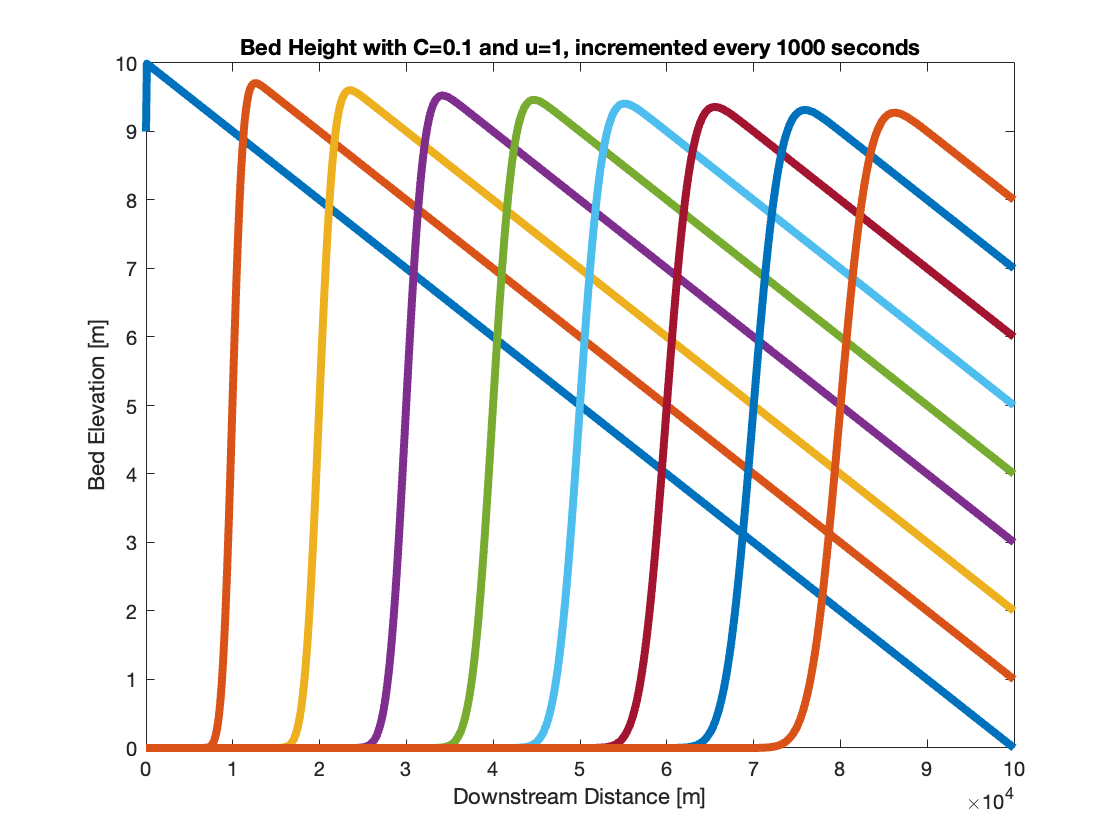

J = zeros(m,1);
Jall = zeros(m,n);

M = sparse(length(x),length(x));

for i = 1:m
    for j = 1:m
        if i==j
            M(i,j) = 1-C;
        elseif i-1==j
            M(i,j) = C;
        end
    end
end

%% Initial Condition

J = eta';

%% Run model

for tt = 1:n
    
    Jnew = M*J;
    Jall(:,tt) = transpose(Jnew);
    J = Jnew;
    
end

%% Plot Model
figure(2)
plot(x,Jall(:,1:dt*100:end),'LineWidth',4);
title('Bed Height with C=0.1 and u=1, incremented every 1000 seconds');
xlabel('Downstream Distance [m]');
ylabel('Bed Elevation [m]');

Repeat for C=1 and U=0.1:

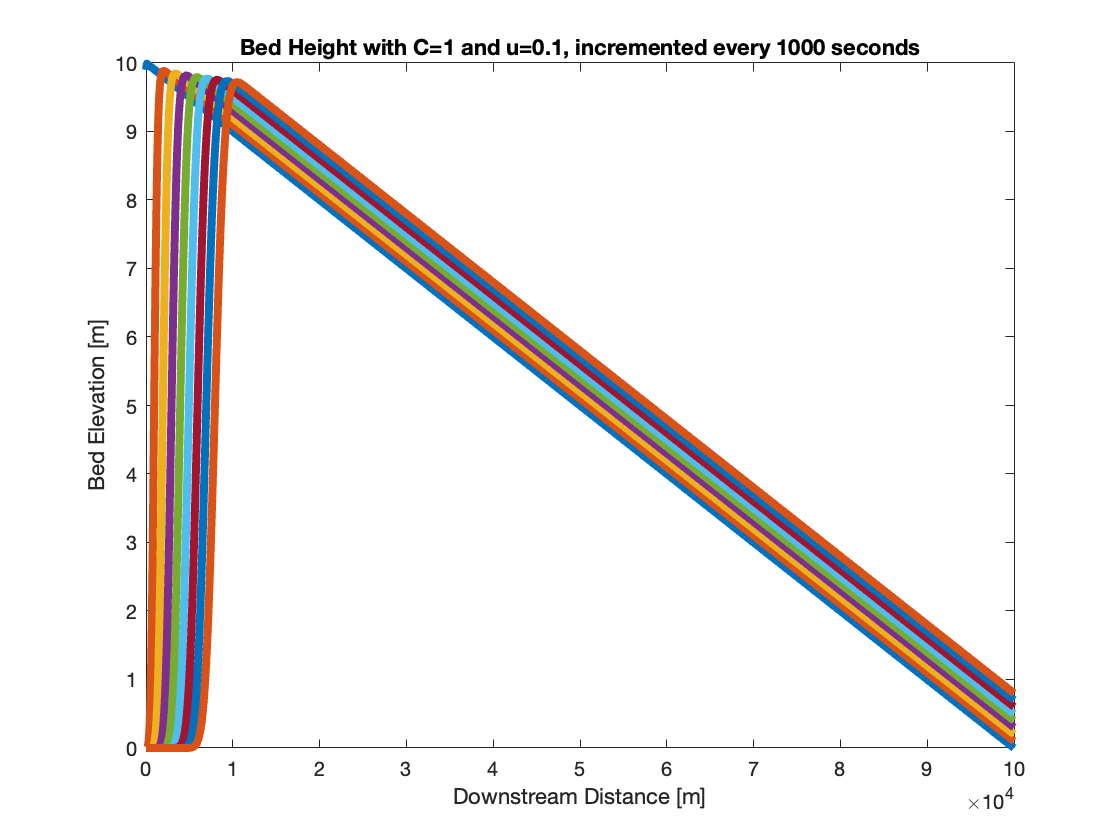

u = 0.1;
C = (u*dt)/dx;

h = 10; % height of the beginning of bed, [m]
eta = linspace(h,0,m); % bed elevation relative to some fixed datum, [m]

e = 0.6; % bed porosity

%% Dirichlet Boundary Condition

eta(1) = 10; % [m], 990 used in paper
eta(end) = 0; % [m]

%% Pre-Allocated Matrices and Time Steps

J = zeros(m,1);
Jall = zeros(m,n);

%% Upwind Advection Equation Matrix

M = sparse(length(x),length(x));

for i = 1:m
    for j = 1:m
        if i==j
            M(i,j) = 1-C;
        elseif i-1==j
            M(i,j) = C;
        end
    end
end

%% Initial Condition

J = eta';

%% Run model

for tt = 1:n
    
    Jnew = M*J;
    Jall(:,tt) = transpose(Jnew);
    J = Jnew;
    
end

%% Plot Model
figure(3)
plot(x,Jall(:,1:dt*100:end),'LineWidth',4);
title('Bed Height with C=1 and u=0.1, incremented every 1000 seconds');
xlabel('Downstream Distance [m]');
ylabel('Bed Elevation [m]');

River parameters:

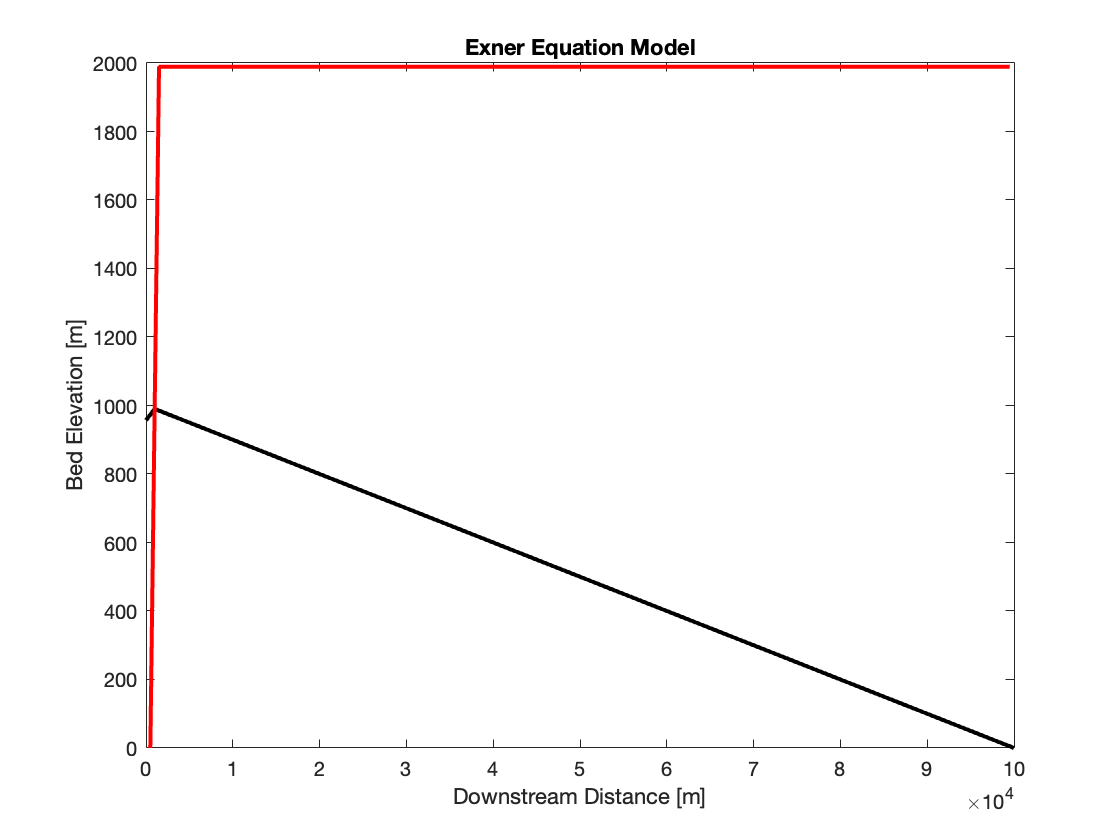

n = 1000:-10:0; % bed elevation relative to some fixed datum
dt = 0.1; % time (seconds)
e = 0.6; % bed porosity
dx = 1000; % regular intervals
x = 0:dx:100000;
t = 0:dt:10;

n(1) = 990;

rho_s = 2.65;
rho_f = 1;
D50 = 0.05; 
g = 9.81; 
h = 100;

D = 0.1; %
Cd = (D*dt)./(dx.^2); %

for i = 1:length(x)-1
    dn = diff(n);
    % dx = np.diff(x)
    tau_b = (rho_f * g * h * (-dn / dx));
    tau_c = 0.0495 * (rho_s - rho_f) * g * D50;
    qs = 4 * (tau_b - tau_c/(((rho_s / rho_f) * g))).^ 1.5 * (((rho_s / rho_f) - 1) * g); % sediment flux
    qs(tau_b<tau_c) = 0; % no sed flux
    dqs = diff(qs);
    dn_dt = -1/e * dqs / dx;
    n(1:end-2) = n(1:end-2) + (dn_dt * dt);
end

figure(4)
plot( x, n, 'k-', 'linewidth', 2)
hold on
plot((x(1:end-1)+x(2:end))./2,qs,'r-','linewidth', 2)
xlabel('Downstream Distance [m]')
ylabel('Bed Elevation [m]')
title('Exner Equation Model')

## Numerical Methods

The model outlined within this file will use the Upwind Advection differencing method, which takes into account dual effects from advection and diffusion, which is evaluated inside of the upwind term. Compared to both schemes, this form of the upwind advection scheme is dependent on the Courant number of the solution, which is essential in assessing stability and diffusivity as changes in trends and observations were made in the model. For Courant numbers larger than 1, the method becomes unstable as a result of the ambient flow skipping gridspaces. Therefore, our model had to utilize values of dt and dx such that the method would becomes stable (C<1), and preferably nondiffusive (C=1). 

## Results

While working with the data, one simulation ran was looking at how changing the porosity changed the overall results. Porosity (e) is the fraction of the total soil volume that is taken up by the pore space. In theory, an increase in porosity would be coincident with an increase in bed elevation. However, our model reveals no changes in bed elevation as it pertains to the porosity of the sediments, which could be dependent on the concentration and amount of sediments within the river. Since porosity is the amount of pore space, when there is more pore space the particles are less densley packed together which results in a higher bed elevation. With less pore space, the particles are able to pack together and lead to a lower bed level because the particles can fill more spaces. 

Another simulation performed was changing the flow velocity (u) in conjunction to the changes in the Courant number to evaluate the effects of stream velocity on sediment transport. When flow velocity is increased, sediment transport increases; however, the change in bed elevation decreases given the rate of advection and fixed concentration and porosity of sediments through this simulation. Within the Upwind Advection scheme, an increase in stream velocity will yield an increase in the Courant number, which makes the model less diffusive, before becoming unstable if the Courant number exceeds 1. While this model did not simulate Courant numbers larger than 1, the model would not be an accurate representation of the Earth system.

## Conclusion

The bed topography vs downstream distance was first graphed as Figure 1. This shows that the sediment transport process is a proportional relationship between bed elevation and downstream distance. This is supported as the Exner equation states that "bed elevation increases proportionally to the amount of sediment that drops out of transport, and conversely decreases proportionally to the amount of sediment that becomes entrained by the flow" (Wikimedia Foundation). 

The model then showed that sediment transport is represented by a sinusoidal wave with the lowest streamline of the flow also "assumed to be a sinusoid" (Kennedy). The transport of sediment measured at "near-bed flow velocity under broken waves often follows a saw tooth shape" which Figures 2 and 3 show (Hsu & Hanes). The immediate spike in bed elevation occurs most likely from a duration of large free-stream acceleration. The large sediment transport under the wave crest occurs after this so it seems that the "transport processes, including the erosion depth, may be correlated to the flow acceleration, though not instantaneously" (Hsu & Hanes). The saw tooth shape is further expected in an environment such as this one due to the unsteady conditions of the broken waves and the horizontal particle motion. 

The model can be improved in terms of methods used and processes included by focusing on creating a more realistic application of the model. Currently, porosity is a component involved in the equations to determine bed elevation but when porosity is changed, the model shows that there is no effect on the resulting elevations. This produces an unrealistic model as all points measured in the stream should be changing with porosity. Also, currently the model is ignoring outside influences on the bed elevation. To create a more realistic model, it could improve by including processes like plate tectonics, compression related subsidence, turbulence, and eddy diffusivity.

## References

Crosby, B., & Whipple, K. (2004, September). Evolution of Depositional Alluvial River Profiles. MIT OpenCourseWare, Massachusetts Institute of Technology. Retrieved December 4, 2021, from [https://ocw.mit.edu/courses/earth-atmospheric-and-planetary-sciences/12-163-surface-processes-and-landscape-evolution-fall-2004/lecture-notes/](https://ocw.mit.edu/courses/earth-atmospheric-and-planetary-sciences/12-163-surface-processes-and-landscape-evolution-fall-2004/lecture-notes/). 

Fowler A. (2011) Dunes. In: Mathematical Geoscience. Interdisciplinary Applied Mathematics, vol 36. Springer, London. [https://doi.org/10.1007/978-0-85729-721-1_5](https://doi.org/10.1007/978-0-85729-721-1_5)

Hsu, T.-J., & Hanes, D. M. (2004, May 25). Effects of wave shape on sheet flow sediment transport. AGU Journals. Retrieved December 7, 2021, from [https://agupubs.onlinelibrary.wiley.com/doi/10.1029/2003JC002075](https://agupubs.onlinelibrary.wiley.com/doi/10.1029/2003JC002075). 

Kennedy, J. (1963). The mechanics of dunes and antidunes in erodible-bed channels. Journal of Fluid Mechanics, 16(4), 521-544. doi:10.1017/S0022112063000975

Wikimedia Foundation. (2021, June 11). Exner equation. Wikipedia. Retrieved December 4, 2021, from [https://en.wikipedia.org/wiki/Exner_equation](https://en.wikipedia.org/wiki/Exner_equation). 